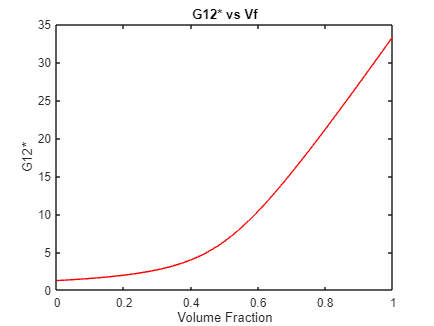

% Self Consistent Method
clear all;
format long e
syms G12_eff G23_eff
syms Vf
% G23_eff Vf k_eff
t = linspace(0,1,100);
% Volume fraction
% Vf = 0.5;
Vm = 1.0 - Vf;
% stiffness matrix of fibre
% Fibre is transversely isotropic with following properties in GPa
E1 = 80;
E2 = 80;
E3 = E2;
%
G12 = 33.33;
G13 = 33.33;
%
G23 = 33.33;
%
nu_12 = 0.2;
nu_13 = nu_12;
%
nu_23 = E2/(2.0 * G23) - 1.0;
%
nu_21 = nu_12 * E2/E1;
nu_31 = nu_13 * E3/E1;
nu_32 = nu_23 * E3/E2;
% Initialization
s = zeros(6,6);
Cf = zeros(6,6);
Cm = zeros(6,6);
%
s(1,1)=1.0/E1;
s(2,2)=1.0/E2;
s(3,3)=1.0/E3;
%
s(1,2)=-nu_21/E2;
s(1,3)=-nu_31/E3;
%
s(2,1)=-nu_21/E2;
s(2,3)=-nu_32/E3;
%
s(3,1)=-nu_13/E1;
s(3,2)=-nu_23/E2;
% Following order is according order in Abaqus
s(4,4)=1.0/G12;
s(5,5)=1.0/G13;
s(6,6)=1.0/G23;
Cf = inv(s);
% Calculate the stiffness matrix of matrix
% Matrix is isotropic with following properties
E0 = 3.35;
XNU = 0.35;
%
XX = E0 * (1.0 - XNU)/((1.0 - 2.0 * XNU)*(1.0 + XNU));
YY = E0 * XNU/((1.0 - 2.0 * XNU)*(1.0 + XNU));
ZZ = E0 /(2.0 * (1.0 + XNU));
%
for I = 1:3
    for J = 1:3
        Cm(I,J) = YY;
    end
    Cm(I,I) = XX;
    Cm(I+3,I+3) = ZZ;
end
Gm = ZZ;
Gf = G12;
kf = E1/(3*(1-nu_21));
km = E0/(3*(1-XNU));


eqn1 = 1/(2*G12_eff)-Vf/(G12_eff-Gm) - (1-Vf)/(G12_eff-Gf); 
G12_eff = solve(eqn1,G12_eff);
G12_efff = zeros(1,100);
for K = 1 : 100
    sign = subs(G12_eff, Vf, t(K));
    if sign(1)>=0
        G12_efff(1,K) = sign(1);
    elseif sign(2)>=0
        G12_efff(1,K) = sign(2);
    end
end
plot(t,G12_efff,'r','Linewidth',0.2);
title("G12* vs Vf")
xlabel("Volume Fraction")
ylabel("G12*")


eqn2 = ((Vf*kf)/(kf+G23_eff))+(((1-Vf)*km)/(km+G23_eff))-2*(((Vf*Gm)/(Gm-G23_eff))+((1-Vf)*Gf)/(Gf-G23_eff)); 
G23_eff = solve(eqn2,G23_eff)

 
G23_eff =
 
        [                     1/3
        [               -16 %3                     -16
        [0.1666666667 10    ----- + 0.6666666667 10
        [                    %1
        [

                       72   2                  72                     72
        0.6838153339 10   Vf  - 0.9164740574 10   Vf + 0.3295778254 10
        ----------------------------------------------------------------
                                         1/3
                                    %1 %3

                                             36                     36]
                          -16 0.8356266548 10   Vf - 0.5629212203 10  ]
         - 0.3333333333 10    ----------------------------------------]
                                                 %1                   ]
                                                                      ]

        [                      1/3
        [                -17 %3                     -16
        [-0.8333333333 10    ----- - 0.333333

G23_efff = zeros(1,100);
k_eff = zeros(1,100);
for K = 1 : 100
    sign = subs(G23_eff, Vf, t(K))
    if sign(1)>=0
        G23_efff(1,K) = sign(1);
    elseif sign(2)>=0
        G23_efff(1,K) = sign(2);
    elseif sign(3)>=0
        G23_efff(1,K) = sign(3);
    end
    k_eff(K) = (1/((t(K)/(kf+G23_efff(K)))+((1-t(K))/(km+G23_efff(K)))))+G23_efff(K);
end

 
sign =
 
                     [                          -8       ]
                     [    -33.33333334 - 0.99 10    i    ]
                     [                                   ]
                     [                              -6   ]
                     [-0.837393232 + 0.1607845727 10    i]
                     [                                   ]
                     [                             -6    ]
                     [1.240740732 - 0.1509845727 10    i ]
 
sign =
 
                     [                          -8       ]
                     [    -33.01257730 - 0.98 10    i    ]
                     [                                   ]
                     [                              -6   ]
                     [-0.838146279 + 0.1607845727 10    i]
                     [                                   ]
                     [                             -6    ]
                     [1.257720439 - 0.1509845727 10    i ]
 
sign =
 
                     [ 

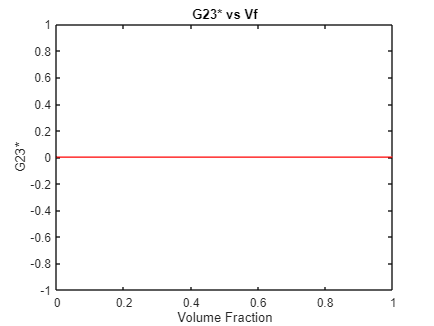

plot(t,G23_efff,'r','Linewidth',0.2);
title("G23* vs Vf")
xlabel("Volume Fraction")
ylabel("G23*")

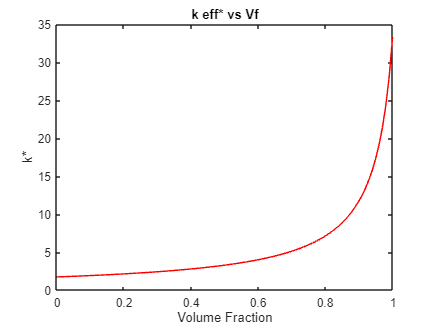

plot(t,k_eff,'r','Linewidth',0.2);
title("k eff* vs Vf")
xlabel("Volume Fraction")
ylabel("k*")